# **Constantes**

C_max    = 15;        %ml/mmHg
C_min    = 0.4;       %ml/mmHg
C_art    = 2;         %ml/mmHg
I_art    = 10^(-4);   %mmHg.s²/ml
p_LA     = 8;         %mmHg
p_RA     = 3;         %mmHg
R_hArt   =  0.1;      %mmHg.s/ml
R_hCap   = 1;         %mmHg.s/ml
R_AV     = 0.1;       %mmHg.s/ml
R_MV     = 10^(-2);   %mmHg.s/ml
V_r      = 5;         %ml
T_ccRef  = 6/7;       %s
T_cc = 6/7;           %s, 60BPM

%T_cc = 0.35; %able to choose cardiac rythm time

# **Definition de C_LV et de sa dérivée**

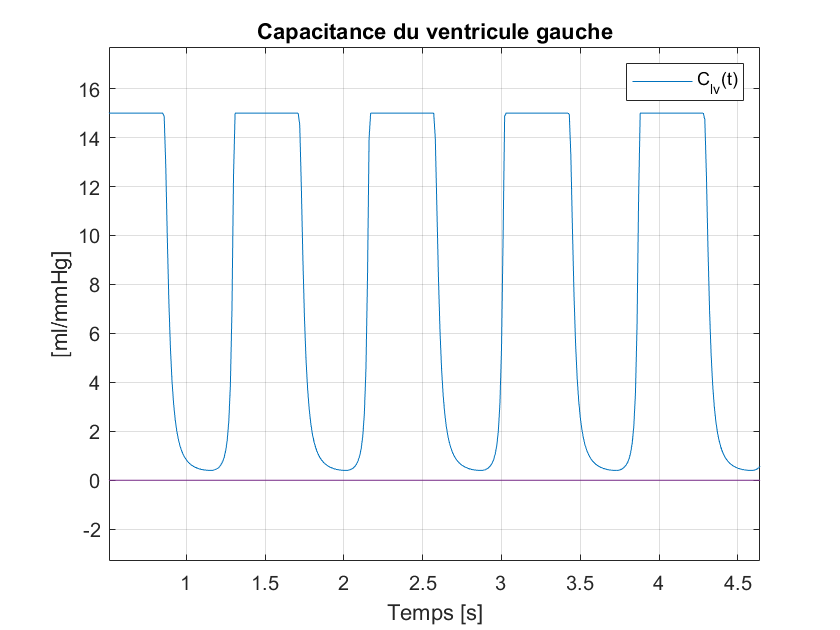

x = 0:1/100:5;
%x = 0:1/1000:5;
clv = zeros(length(x));
for i=1:length(x)
    clv(i)=capLV(x(i),T_cc,C_min,C_max);
end

plot(x,clv) 
xlabel('Temps [s]')
ylabel('[ml/mmHg]')
title('Capacitance du ventricule gauche')
xlim([0.51 4.64])
ylim([-3.3 17.7])
legend('C_{lv}(t)')
grid on
hold off

%TODO DÉRIVÉE pour l'instant approx par f(x+dt) -f(x) / x+dx - x

%x = 0:1/1000:5; Prend bpc de temps mais graph plus beau
x = 0:1/100:5;
pclv = zeros(length(x));
for i=1:length(x)
    pclv(i)=primeCapLV(x(i),T_cc,C_min,C_max);
end


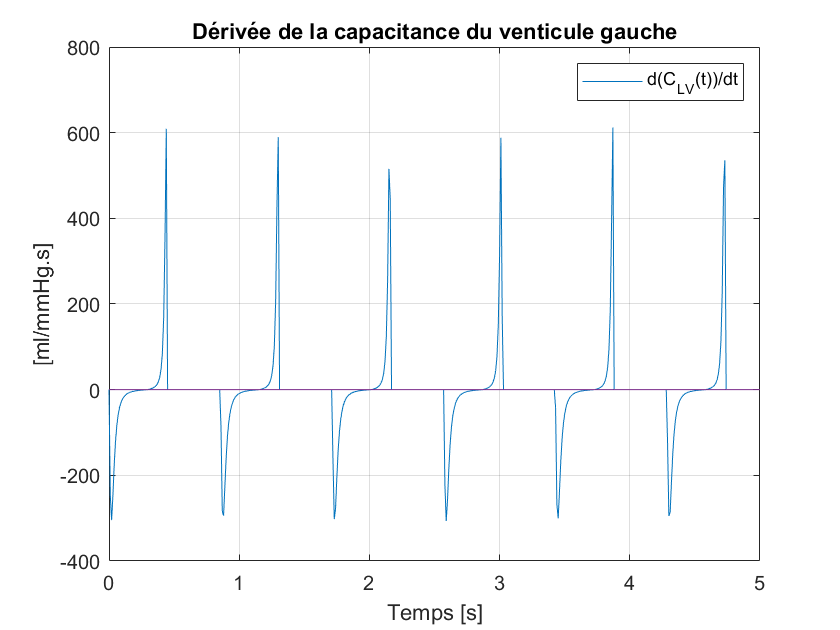

plot(x,pclv)
xlabel('Temps [s]')
ylabel('[ml/mmHg.s]')
title('Dérivée de la capacitance du venticule gauche')
legend("d(C_{LV}(t))/dt")
grid on
hold off

# **Résolution pour la circulation systémique chez la personne sain**

tspan = [-10 10];
y0 = [150 120 70];%À vérifier
[t,y] = ode45(@(t,y) odefcn(t,y,T_cc,C_min,C_max,p_LA,R_MV,I_art,R_hArt,R_hCap,p_RA,R_AV,C_art), tspan, y0);

Compute Other elements of system

Q0 = ((p_LA-y(:,1))./R_MV).*heaviside(p_LA-y(:,1));
Q1 = ((y(:,1)-y(:,3))./R_AV).*heaviside(y(:,1)-y(:,3));
V_LV_vec = zeros(1,length(t));
for i=1:length(t)
    V_LV_vec(i) = y(i,1)*capLV(t(i),T_cc,C_min,C_max)-V_r;
end
C_LV_vec = zeros(1,length(t));
for i=1:length(t)
    C_LV_vec(i) = capLV(t(i),T_cc,C_min,C_max);
end
C_LV = C_LV_vec.';
V_LV = V_LV_vec.';

# **Résultats en graphiques pour la circulation systémique chez la personne sain**

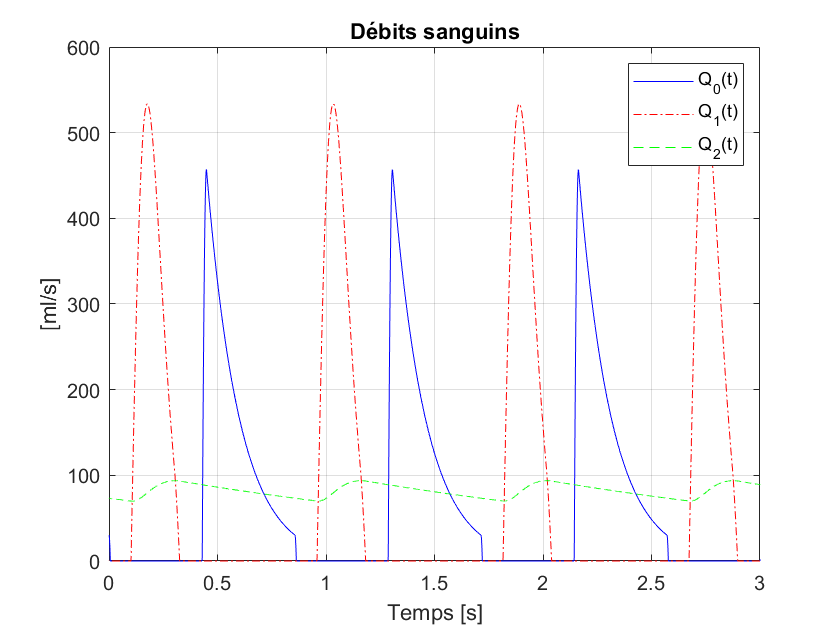

plot(t,Q0,'-b',t,Q1,'-.r',t,y(:,2),'--g')
xlabel('Temps [s]')
ylabel('[ml/s]')
legend('Q_{0}(t)', 'Q_{1}(t)','Q_{2}(t)')
title('Débits sanguins')
xlim([0 3])
ylim([0 600])
grid on
hold off

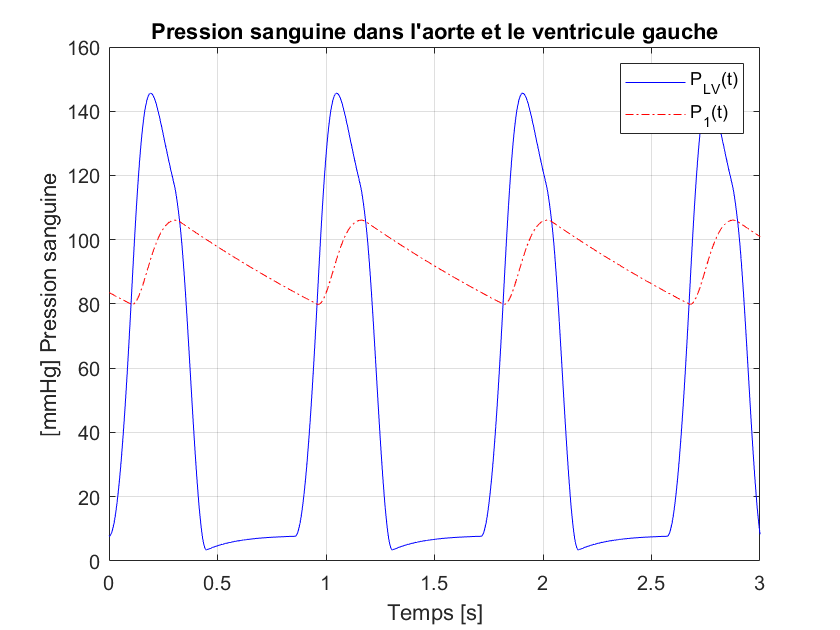

plot(t,y(:,1),'-b',t,y(:,3),'-.r')
xlabel('Temps [s]')
legend('P_{LV}(t)','P_{1}(t)')
ylabel("[mmHg] Pression sanguine")
title("Pression sanguine dans l'aorte et le ventricule gauche")
xlim([0 3])
ylim([0 160])
grid on
hold off

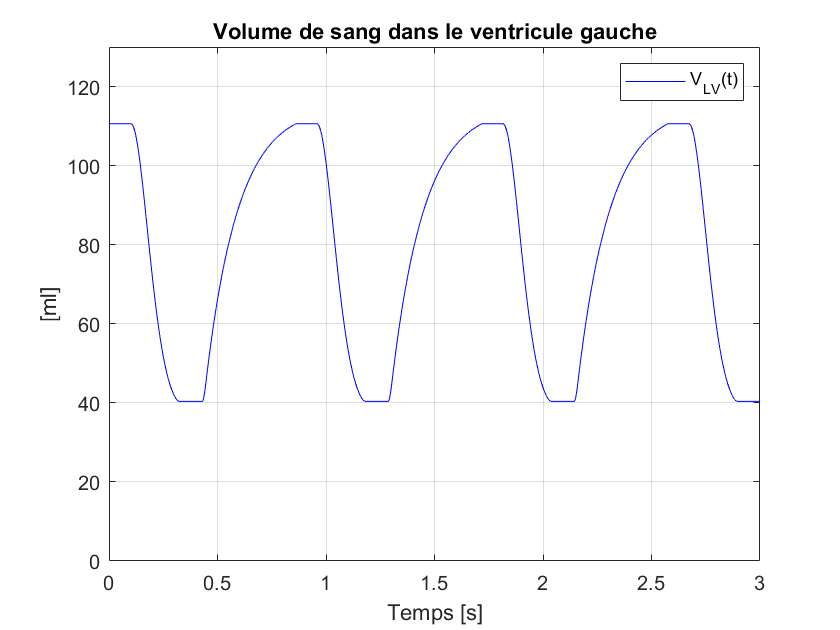

plot(t,V_LV,'-b')
xlabel('Temps [s]')
legend('V_{LV}(t)')
ylabel('[ml]')
title('Volume de sang dans le ventricule gauche')
xlim([0 3])
ylim([0 130])
grid on
hold off

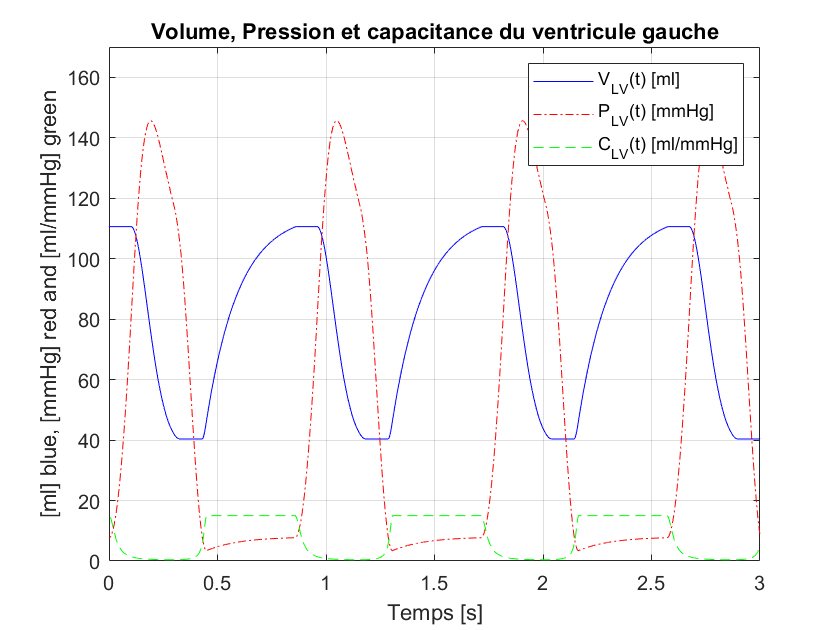

plot(t,V_LV,'-b',t,y(:,1), '-.r',t,C_LV,'--g')
xlabel('Temps [s]')
legend('V_{LV}(t) [ml]','P_{LV}(t) [mmHg]','C_{LV}(t) [ml/mmHg]')
ylabel('[ml] blue, [mmHg] red and [ml/mmHg] green')
title('Volume, Pression et capacitance du ventricule gauche')
xlim([0 3])
ylim([0 170])
grid on
hold off

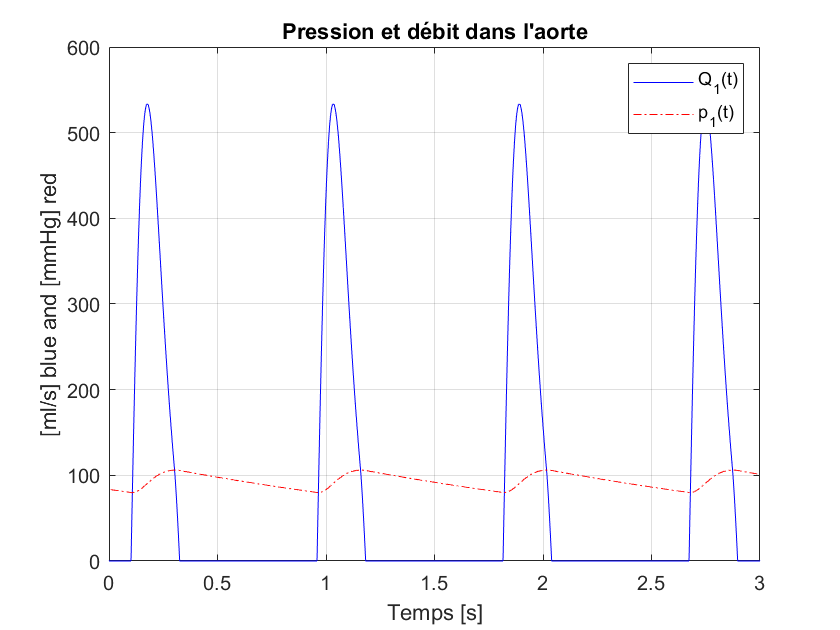

plot(t,Q1,'-b',t,y(:,3), '-.r')
xlabel('Temps [s]')
legend('Q_1(t)','p_1(t)')
ylabel('[ml/s] blue and [mmHg] red')
title("Pression et débit dans l'aorte")
xlim([0 3])
ylim([0 600])
grid on
hold off

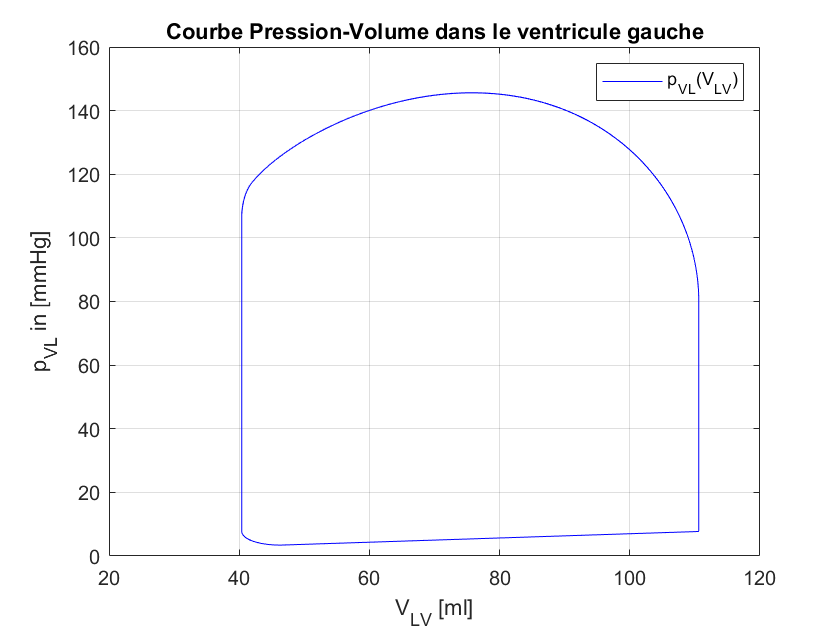

plot(V_LV(fix(length(t)/2):end,1),y(fix(length(t)/2):end,1),'-b')
ylabel('p_{VL} in [mmHg]')
legend('p_{VL}(V_{LV})')
xlabel('V_{LV} [ml]')
title('Courbe Pression-Volume dans le ventricule gauche')
xlim([20 120])
ylim([0 160])
grid on
hold off

# **FUNCTION DEFINTION**

function c_lv = capLV(t,T_cc,C_min,C_max)
    T_ccRef  = 6/7; 
    t_rel = mod(t,T_cc); 
    T_vc = 0.3*(T_cc/T_ccRef);
    T_vr = 0.15*(T_cc/T_ccRef);
    if ((0 < t_rel) && (t_rel <= T_vc))
        ecc = 0.5 * (1 - cos(pi * t_rel / T_vc));
    elseif ((T_vc < t_rel ) && (t_rel  < T_vc + T_vr))
        ecc = 0.5 * (1 + cos(pi* (t_rel -T_vc) / T_vr));
    else 
        ecc = 0;
    end
    c_lv = 1 / ( ( 1/C_min - 1/C_max ) * ecc + 1/C_max);
end

function c_lv_prime = primeCapLV(t,T_cc,C_min,C_max)
    t_else = t+10^(-10);
    c_lv_prime = (capLV(t_else,T_cc,C_min,C_max)-capLV(t,T_cc,C_min,C_max))./(t_else-t);
end

function dydt = odefcn(t,y,T_cc,C_min,C_max,p_LA,R_MV,I_art,R_hArt,R_hCap,p_RA,R_AV,C_art)
  dydt = zeros(3,1);
  %eq 56 p_lv = y(1)
  dydt(1) = (-y(1).*primeCapLV(t,T_cc,C_min,C_max)+((p_LA-y(1))/R_MV).*heaviside(p_LA-y(1))-((y(1)-y(3))./R_AV).* heaviside(y(1)-y(3)))./capLV(t,T_cc,C_min,C_max);
  %eq 57  Q2 = y(2)
  dydt(2) =  (y(3)-p_RA-(R_hCap+R_hArt).*y(2))./I_art;
  %eq 58 p1 = y(3)
  dydt(3) = (((y(1)-y(3))./R_AV).*heaviside(y(1)-y(3))-y(2))./C_art;
end
